% Step 1: Predefined MFCC Features (Assume Preprocessed Data)
% Replace with your actual MFCC feature matrix
T = 10; % Number of time frames
numCoeffs = 13; % Number of MFCC coefficients
mfccFeatures = rand(T, numCoeffs); % Random data for testing (replace with real features)

% Normalize MFCC features
meanFeature = mean(mfccFeatures, 1);
stdFeature = std(mfccFeatures, 1);
normalizedMFCC = (mfccFeatures - meanFeature) ./ stdFeature;

% Step 2: Initialize HMM Parameters
N = 8; % Number of HMM states

% Initialize State Transition Matrix (Left-right HMM)
A = zeros(N, N);
for i = 1:N-1
    A(i, i) = 0.8; % Self-loop probability
    A(i, i+1) = 0.2; % Transition to next state
end
A(N, N) = 1.0; % Final state self-loop
A = A ./ sum(A, 2); % Normalize rows to sum to 1

% Initialize Emission Probabilities (Random for simplicity)
B = rand(N, T); % Random probabilities
B = B ./ sum(B, 1); % Normalize columns to sum to 1

% Initialize Initial State Probabilities
pi = zeros(N, 1);
pi(1) = 1.0; % Start in the first state
pi = pi / sum(pi);

% Step 3: Implement the Viterbi Algorithm
function [optimalPath, delta, psi] = viterbiAlgorithm(O, A, B, pi)
    % Inputs:
    % O - Observation sequence (T x K matrix, features not used here directly)
    % A - State transition matrix (N x N)
    % B - Emission probability matrix (N x T)
    % pi - Initial state probabilities (N x 1)

    [N, T] = size(B); % N: Number of states, T: Number of time frames

    % Initialize trellis and backpointer matrices
    delta = zeros(N, T); % Log probabilities
    psi = zeros(N, T);   % Backpointers

    % Initialization
    delta(:, 1) = log(pi) + log(B(:, 1));
    psi(:, 1) = 0; % No backpointer for the first step

    % Recursion
    for t = 2:T
        for j = 1:N
            [delta(j, t), psi(j, t)] = max(delta(:, t-1) + log(A(:, j)) + log(B(j, t)));
        end
    end

    % Termination
    [~, optimalLastState] = max(delta(:, T));

    % Backtracking
    optimalPath = zeros(1, T);
    optimalPath(T) = optimalLastState;
    for t = T-1:-1:1
        optimalPath(t) = psi(optimalPath(t+1), t+1);
    end
end

% Step 4: Call the Viterbi Algorithm
[optimalPath, delta, psi] = viterbiAlgorithm(normalizedMFCC, A, B, pi);

% Step 5: Display Results
disp('Optimal State Path:');

Optimal State Path:


disp(optimalPath);

     1     1     1     1     1     1     1     1     1     1




% Step 6: Evaluate Results
% Assume ground truth labels
trueLabels = [1, 2, 2, 3, 3, 4, 5, 6, 7, 8]; % Example ground truth labels
predictedLabels = optimalPath(1:length(trueLabels));
errorRate = sum(trueLabels ~= predictedLabels) / length(trueLabels);
fprintf('Recognition Error Rate: %.2f%%\n', errorRate * 100);

Recognition Error Rate: 90.00%



% Generate Confusion Matrix
confusionMatrix = confusionmat(trueLabels, predictedLabels);
disp('Confusion Matrix:');

Confusion Matrix:


disp(confusionMatrix);

     1     0     0     0     0     0     0     0
     2     0     0     0     0     0     0     0
     2     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0



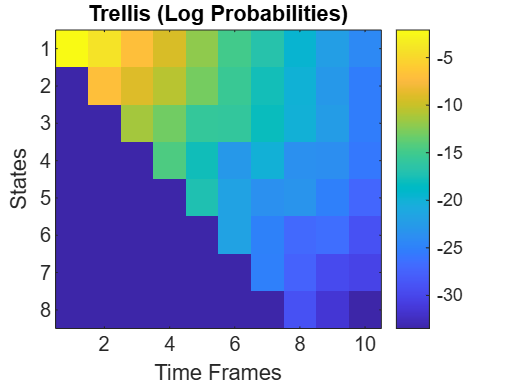


% Plot Trellis
figure;
imagesc(delta);
colorbar;
xlabel('Time Frames');
ylabel('States');
title('Trellis (Log Probabilities)');